# Analisis de Propiedades Mecanicas de Materiales

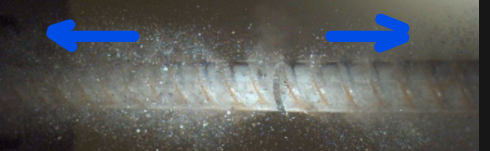

## Define General Parameters

D = 12 * 10^(-3); %Diametro inicial 
Df = 11.74 * 10^(-3); %Diametro Final
Lf = 32.61 * 10^(-3); %Longitud Final

F = [0,5000,10000,15000,25000,26500,27000, 26500, 25000]; %Fuerzas
L = [30, 30.0296,30.0592, 30.15, 30.51, 30.9, 31.5, 32.1, 32.79] * 10^(-3); %Longitudes


## Calculate Values of intrest

%Initialize
sig = zeros(length(F),1); 
eps = sig; 
DiffE = zeros(length(F)-1,1);

%Calculate Areas 
A = pi * D^2/ 4; 
Af = pi * Df^2/ 4; 

for ii = 1:length(F)
    sig(ii) = F(ii)./ A; %Esfuerzo
    eps(ii) = (L(ii)-L(1))/L(1); % Elongacion 
    
    E(ii) = sig(ii)/eps(ii); % Modulo elasticidad
    
    if ii>1
        DiffE(ii-1) = abs(E(ii-1)-E(ii));
        
        if DiffE(ii-1)>max(DiffE)
            b = sig(ii-1); 
        end
        
    end
     
end


## Present Results

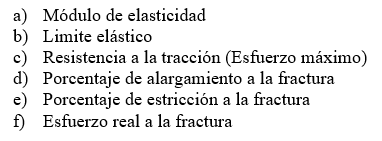

a = E(2)

a = 4.4807e+10

%b = b
c = max(sig) 

c = 2.3873e+08

d = (L(end)-L(1))/ L(1)

d = 0.0930

e = (Lf-L(1))/ L(1)

e = 0.0870

f = F(end)/ Af

f = 2.3095e+08

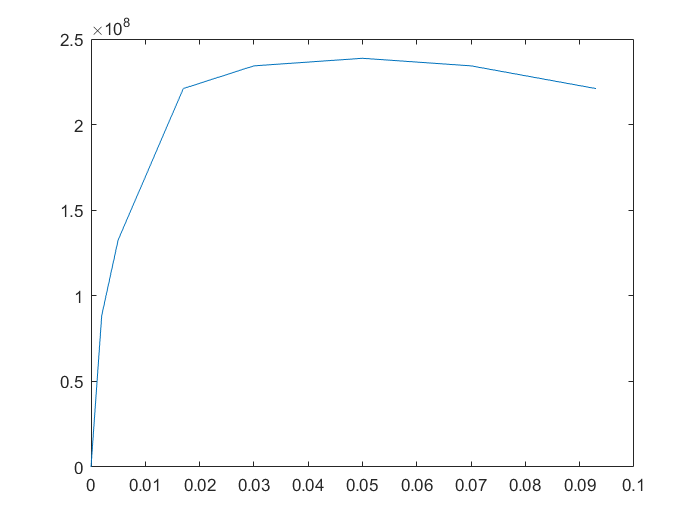


plot(eps,sig)